data = csvread("friktion1.csv")

data =    -9.3800    0.0041
   -9.3700    0.0101
   -9.3600    0.0282
   -9.3500    0.0423
   -9.3400    0.0684
   -9.3300    0.0986
   -9.3200    0.1327
   -9.3100    0.1729
   -9.3000    0.2091
   -9.2900    0.2473


time = data(:,1) + (10 - 0.62)

time =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


voltage = data(:,2) - 0.6836

voltage =    -0.6795
   -0.6735
   -0.6554
   -0.6413
   -0.6152
   -0.5850
   -0.5509
   -0.5107
   -0.4745
   -0.4363



t = time'

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



% for i=1:size(time)
%     t(1,i) = i;
% end

% For finding mean
% for i=1800:1900
%     test(i-1799) = voltage(i);
% end

ang = voltage.* (90/1.4)

ang =   -43.6821
  -43.2964
  -42.1329
  -41.2264
  -39.5486
  -37.6071
  -35.4150
  -32.8307
  -30.5036
  -28.0479


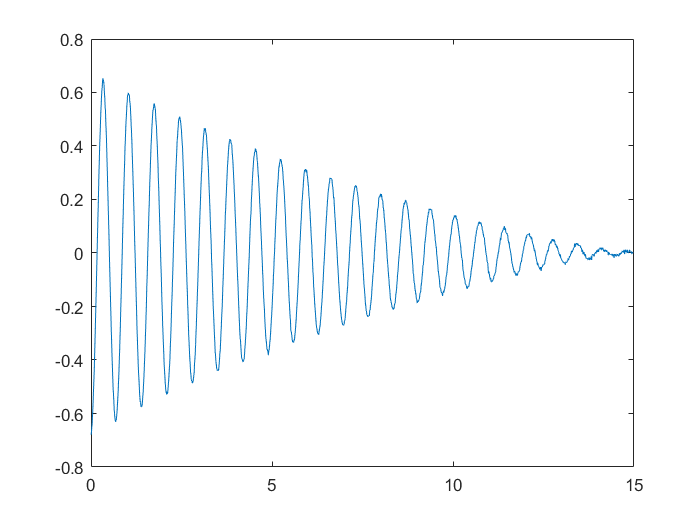

u = zeros(1499,1);
y = ang;
plot(t,voltage)

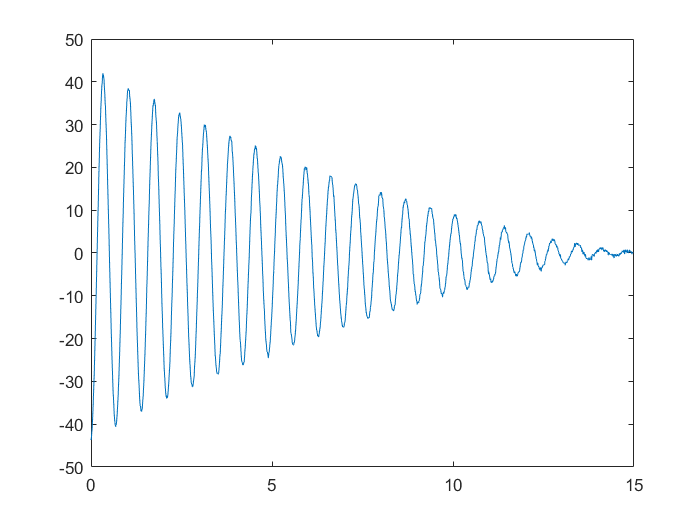

plot(t,ang)

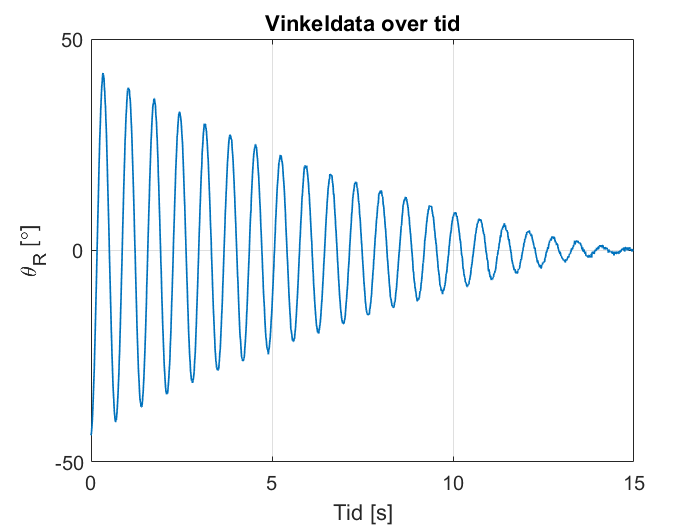

clc
clear
load('measinertia.mat')

plot(t,y, 'linewidth', 1)
set(gca,'FontSize',12)
title('Vinkeldata over tid')
xlabel("Tid [s]")
ylabel("\theta_R [\circ]")
grid on